s = tf("s")

s =
 
  s
 
Continuous-time transfer function.





sys = ss(A,B,C,D)

Unrecognized function or variable 'A'.

sys = ss(sys)

L=place(A,B,p)
L=acker(A,B,p)


%6.10
G1 = 725 / ((s+1)*(s+2.5)*(s+25))

G1 =
 
                
             725
                
  --------------------------
                            
  s^3 + 28.5 s^2 + 90 s     
                            
                      + 62.5
                            
 
Continuous-time transfer function.




Go1 = G1 * 1/(s+1)

Go1 =
 
                 
              725
                 
  ---------------------------
                             
  s^4 + 29.5 s^3 + 118.5 s^2 
                             
            + 152.5 s + 62.5 
                             
 
Continuous-time transfer function.




F1 = 0.46*(0.43*s+1)/(0.09*s+1)*(2*s+1)/2*s

F1 =
 
                            
  0.3956 s^3 + 1.118 s^2    
                            
                    + 0.46 s
                            
  --------------------------
                    
          0.18 s + 2
                    
 
Continuous-time transfer function.




T1 = F1 * G1/(1+F1*G1)

T1 =
 
                            
  51.63 s^7 + 2191 s^6      
                            
          + 2.683e04 s^5    
                            
          + 1.166e05 s^4    
                            
          + 2.153e05 s^3    
                            
          + 1.651e05 s^2    
                            
                + 4.169e04 s
                            
  --------------------------
                            
  0.0324 s^8 + 54.19 s^7    
                            
          + 2268 s^6        
                            
          + 2.795e04 s^5    
                            
          + 1.247e05 s^4    
                            
          + 2.45e05 s^3     
                            
          + 2.2e05 s^2      
                            
           + 89500 s + 15625
                            
 
Continuous-time transfer function.



T2 = G1/(1+G1) % F=1

T2 =
 
                            
  725 s^3 + 2.066e04 s^2    
                            
          + 65250 s         
                            
                  + 4.531e04
                            
  --------------------------
                            
  s^6 + 57 s^5 + 992.2 s^4  
                            
          + 5980 s^3        
                            
          + 32325 s^2       
                            
          + 76500 s         
                            
                  + 4.922e04
                            
 
Continuous-time transfer function.



clf
DeltaG1 = (-s/(s+1))

DeltaG1 =
 
   -s
  -----
  s + 1
 
Continuous-time transfer function.





hold on
h = bodeplot(1/DeltaG1);
h3 = bodeplot(T1)


h3 =

	resppack.bodeplot



h2 = bodeplot(T2)


h2 =

	resppack.bodeplot



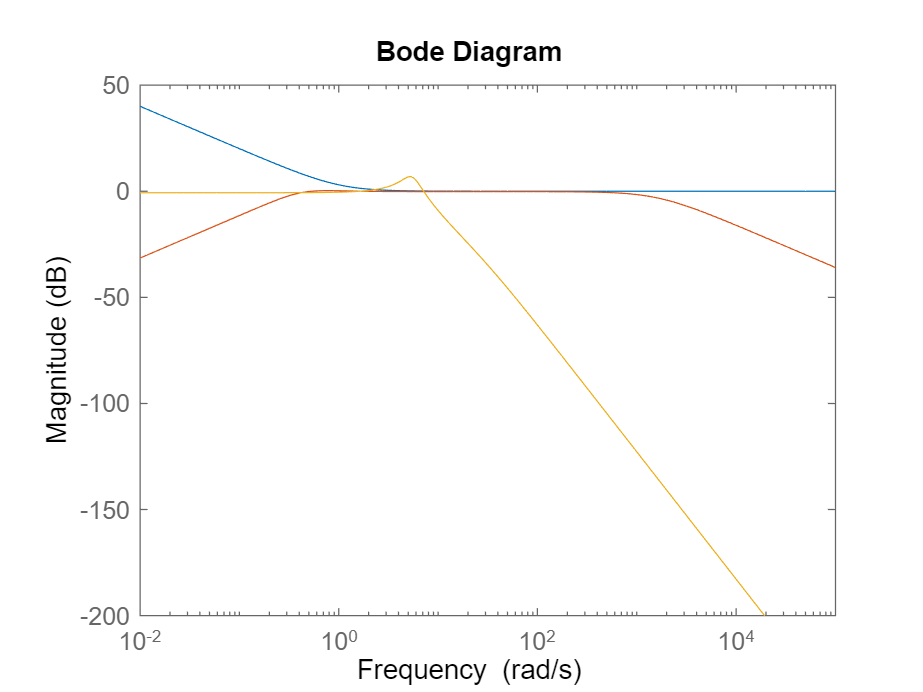


setoptions(h,'PhaseVisible', 'off')
setoptions(h2,'PhaseVisible', 'off')
setoptions(h3, 'PhaseVisible', 'off')

%9.14

clear
s = tf("s")

s =
 
  s
 
Continuous-time transfer function.




G2 = 1/(s*(s+1))

G2 =
 
     1
  -------
  s^2 + s
 
Continuous-time transfer function.



p = [-2.2 -2.1]

p =    -2.2000   -2.1000


p2 = [-1-i -1+i]

p2 =   -1.0000 - 1.0000i  -1.0000 + 1.0000i



sys = ss(G2)

sys =
 
  A = 
       x1  x2
   x1  -1   0
   x2   1   0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




%sys = ss(sys)

L=place(sys.A,sys.B,p2)

L =      1     2


L=acker(sys.A,sys.B,p2)

L =      1     2



eig(sys.A - sys.B * L)

ans =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i



%method 1


%Ys1 = sys.C((s*I) - inv(sys.B*L))*sys.B*Lr*R


Lr = -1/(sys.C * inv(sys.A-sys.B*L)*sys.B)

Lr = 2


I = eye(2,2)*s

I =
 
  From input 1 to output...
   1:  s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
   2:  s
 
Continuous-time transfer function.



Gc1 = sys.C * inv(I - (sys.A-sys.B*L))*sys.B*Lr

Gc1 =
 
        2
  -------------
  s^2 + 2 s + 2
 
Continuous-time transfer function.



%step(Gc1) %use cmdwin

[num, den]= ss2tf(sys.A-sys.B*L, sys.B*Lr, sys.C, 0)

num =      0     0     2


den =     1.0000    2.0000    2.0000


Gc = tf(num ,den)

Gc =
 
        2
  -------------
  s^2 + 2 s + 2
 
Continuous-time transfer function.




eig(Gc)

ans =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i



%c 

Q1 = [ 0 0 ; 0 1]

Q1 =      0     0
     0     1


Q2 = [0 0 ; 0 10]

Q2 =      0     0
     0    10


Q3 = [0 0 ; 0 .1]

Q3 =          0         0
         0    0.1000



%111111111111111111111111111111
Lq1 = lqr(sys.A, sys.B, Q2, 1)

Lq1 =     0.7321    1.0000


Lr = -1/(sys.C * inv(sys.A-sys.B*L)*sys.B)

Lr = 2

Gc2 = ss(sys.A-sys.B*L, sys.B*Lr, sys.C, 0)

Gc2 =
 
  A = 
       x1  x2
   x1  -2  -2
   x2   1   0
 
  B = 
       u1
   x1   2
   x2   0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




[y, t ,x] = step(Gc2, 10)

y =          0
    0.0079
    0.0297
    0.0628
    0.1047
    0.1534
    0.2068
    0.2636
    0.3221
    0.3812


t =          0
    0.0917
    0.1835
    0.2752
    0.3670
    0.4587
    0.5505
    0.6422
    0.7339
    0.8257


x =          0         0
    0.1672    0.0079
    0.3037    0.0297
    0.4128    0.0628
    0.4972    0.1047
    0.5598    0.1534
    0.6033    0.2068
    0.6303    0.2636
    0.6430    0.3221
    0.6438    0.3812


u= -x*L.' + Lr

u =     2.0000
    1.8170
    1.6368
    1.4616
    1.2934
    1.1335
    0.9830
    0.8426
    0.7129
    0.5939


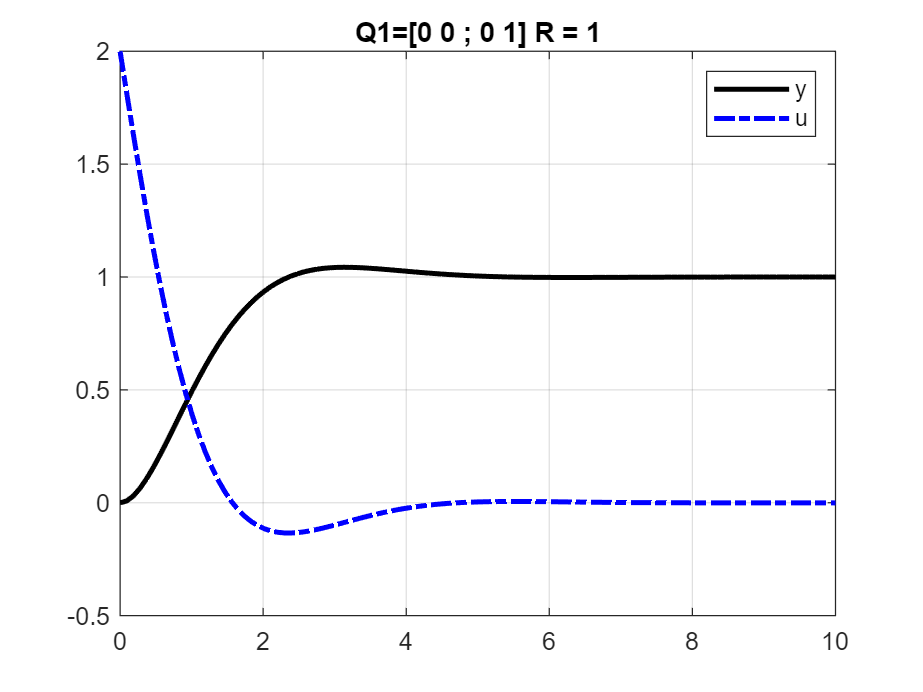

figure
plot(t,y,"k-", t, u, "b-.", "LineWidth",2)
grid
title('Q1=[0 0 ; 0 1] R = 1')
legend("y", "u")


eig(sys.A) %pole(Gc1)

ans =      0
    -1



%2222222222222222222222222222
Lq2 = lqr(sys.A, sys.B, Q2, 1)

Lq2 =     1.7064    3.1623


Gc3 = ss(sys.A-sys.B*L, sys.B*Lr, sys.C, 0)

[y, t ,x] = step(Gc2, 10)
u= -x*L.' + Lr
figure
plot(t,y,"k-", t, u, "b-.", "LineWidth",2)
grid
title('Q2=[0 0 ; 0 10] R = 1')
legend("y", "u")

Lq3 =     0.2777    0.3162


%Lq = transpose(sys.B) * P
%333333333333333333333333333
Lq3 = lqr(sys.A, sys.B, Q3, 1)
Gc3 = ss(sys.A-sys.B*L, sys.B*Lr, sys.C, 0)

[y, t ,x] = step(Gc2, 10)
u= -x*L.' + Lr
figure
plot(t,y,"k-", t, u, "b-.", "LineWidth",2)
grid
title('Q3=[0 0 ; 0 .1] R = 1')
legend("y", "u")
Lq3 = lqr(sys.A, sys.B, Q3, 1)